## Beampattern Notebook

Concepts to communicate:

- Beampattern

- Main Lobe

- Sidelobes

- Beam width

- Source Level

- Near-field vs far-field

A **transducer** is a device that takes an electrical signal and transforms it into mechanical motion. The audio speakers in computers, phones, or headphones are probably the transducers we interact with and use on a daily basis. These transducers use an electrical signal to cause the speaker surface to oscillate which then generates sound. The acoustic source in a sonar system does the same thing. A transducer can also take mechanical motion and transform it into an electrical signal (microphones in air and hydrophones in the water), but this section will focus only on the properties of acoustic transducers that are used to generate sound.

### Circular transducer

The most common man-made sound sources used in underwater acoustics are planer transducers which have flat surfaces which oscillate to produce sound. This is in part due to the fact that a flat transducer is relatively easy to manufacturer, but more importantly, the transducer transmits a majority of the sound in the direction perpendicular to the vibrating plane.  This is a useful property in many sonar systems and this directivity of the transmitted sound can help determine the location of an object (fish, bubble, submarine, etc.)   

Note that we said the transducer directs a "majority" of the sound in one direction and not "all" of the sound. In fact, the transducer sends different levels of sound in many directions and the directional dependence of the sound is refered to as the transducer's **beam pattern**. To help understand the concept of a beam pattern and it's properties, we will focus initially on one particular, common type of tranducer: the circular piston. This type of transducer is often a cylindrical piece of piezoelectric material to which an electrical signal is applied such that it expands and contracts along the axis of the cylinder. The causes sound to radiate from the circular face of the transducer. The structure of the sound field from this type of transducer can be fairly complicated and there is not a simple, mathematical expression for the direction and strength of the transmitted sound. There are, however, approximate mathematical descriptions that can be accurately describe the transmitted sound under certain conditions. One of the most useful of these is to assume that the transducer an be approximated as a baffled circular piston. By "baffled," we mean that the face of the transducer is surrounded by an infinite, rigid surface. This simplifies the mathematics and allows us to calculate strength and direction of the transmitted field.

In the following, the face of the transducer will be in the x-y plane and the z-axis is perpendicular to the face. The radius of the tranducer is $a$ and the field will be described in two ways; either a function of the distance, $r$, from the center of the face and the angle, $\theta$, between the direction of $r$ and the $z$-axis or as a function of distance from the plane of the transducer (range) and the perpendicular direction (cross-range.) 

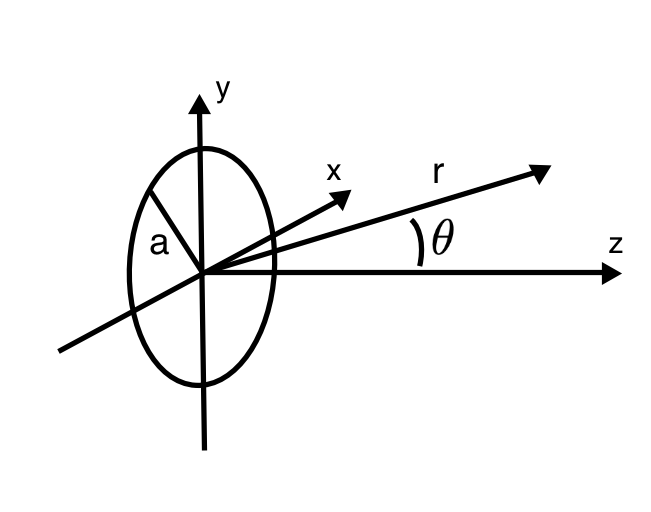

 If the sound is measured far away from the face of the transducer, the intensity of the sound will be proportional to $1/r^2$ and the angular-dependence of the field can be expressed in a simple form that does not depend on the distance. When the reciever is sufficiently far away that these two properties are true, then the receiver is said to be in the **far-field** of the transducer. In the widget below, we've removed the $1/r^2$ dependence and normalized the intensity by the value measured on the z-axis or $\theta = 0^\circ$. As a result, the normalized intensity is 0 dB (or 1 on a linear scale.) The widget allows you to make the transducer larger or smaller by increasing it's radius and allows you to change the frequency of the sound being transmitted. You can also display the angular dependence of the transmitted sound on different plots and on both a linear and decibel scale.

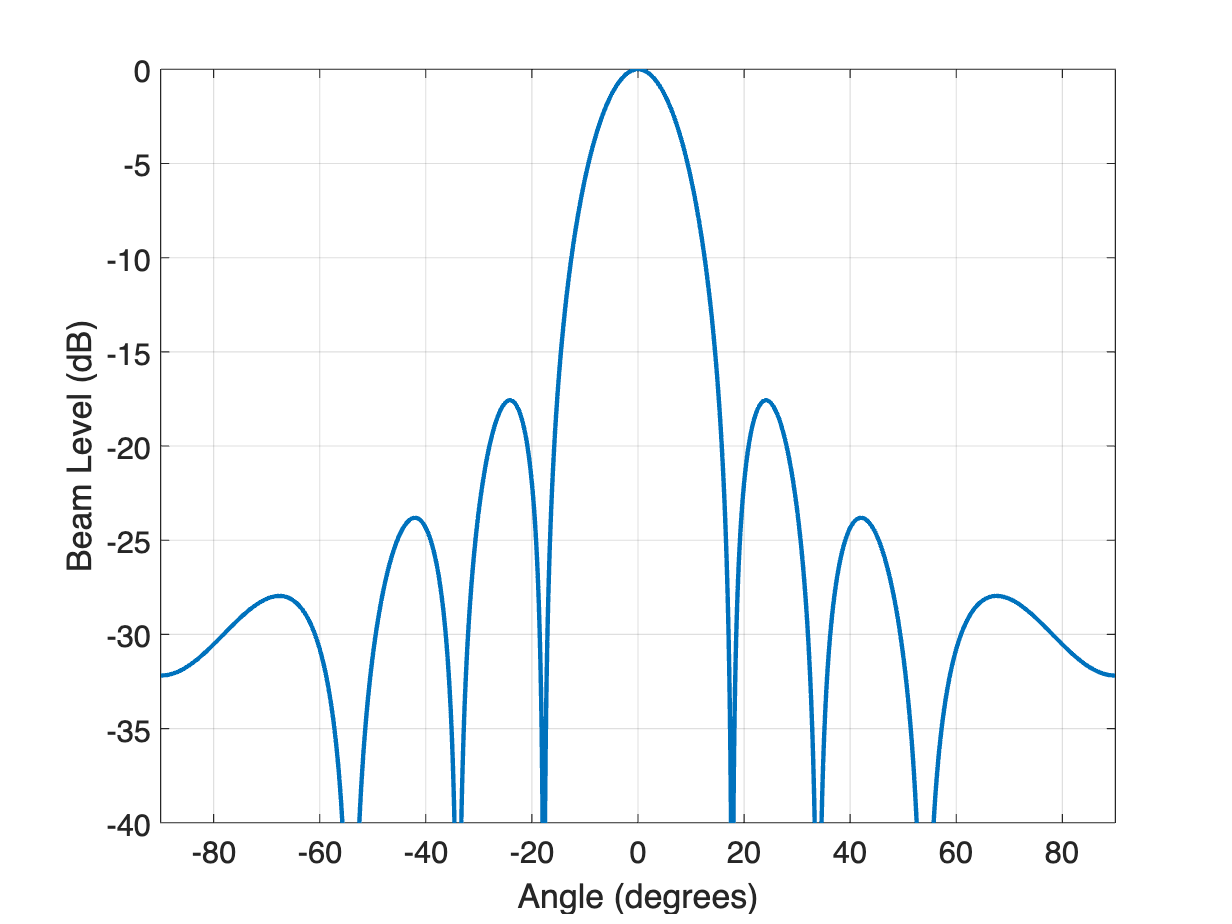

f = 12;      % Frequency in kHz
rho0 = 1;
c = 1500;
a = 0.25;
r = 10;

omega = 2*pi*f*1000;
k = omega/c;

theta = -90:0.1:90;
u = k*a*sin(theta*pi/180);

projInt = abs((rho0*c*k*a*a/(2*r)).*...
    (2*besselj(1,u)./u)).^2;
ind = find(theta == 0);
axisInt = abs(rho0*c*k*a*a/(2*r)).^2;
projInt(ind) = axisInt;

zerosBesselJ1 = [3.83,7.02,10.17];
pressureNulls = asin(zerosBesselJ1/(k*a))*180/pi;
thetaInd = find(theta > pressureNulls(1) & theta < pressureNulls(2));
[SideLobeDB,indSideLobe] = max(10*log10(projInt(thetaInd)/axisInt));
firstSideLobeAngle = theta(thetaInd(indSideLobe));

plotType = 0;
plotScale = "Decibels";

figure(1)
if plotType == 0

    if plotScale == 'Decibels'

        plot(theta,10*log10(projInt/axisInt),'linewidth',2)
        a1 = gca;
        a1.YLim = [-40 0];
        a1.XLim = [-90 90];
        a1.FontSize = 14;
        a1.XLabel.String = 'Angle (degrees)';
        a1.YLabel.String = 'Beam Level (dB)';
        grid on

    else

        plot(theta,projInt/axisInt,'linewidth',2)
        a1 = gca;
        a1.YLim = 10.^([-40 0]/10);
        a1.FontSize = 14;
        a1.XLabel.String = 'Angle (degrees)';
        a1.YLabel.String = 'Beam Level';
        a1.XLim = [-90 90];

    end


elseif plotType == 1

    if plotScale == 'Decibels'

        polarplot(theta*pi/180,10*log10(projInt/axisInt),'linewidth',2)
        a1 = gca;
        a1.RLim = [-40 0];
        a1.ThetaZeroLocation = 'top';
        a1.ThetaLim = [-90 90];
        a1.Title.String = 'Beam Pattern (dB)';
        a1.FontSize = 14;

    else

        polarplot(theta*pi/180,projInt/axisInt,'linewidth',2)
        a1 = gca;
        a1.RLim = 10.^([-40 0]/10);
        a1.ThetaZeroLocation = 'top';
        a1.ThetaLim = [-90 90];
        a1.Title.String = 'Beam Pattern (Linear Scale)';
        a1.FontSize = 14;

    end

end

One of the things you'll notice as you decrease the frequency or decrease the radius, is that the central part of the beam pattern gets wider. This central portion of the beam pattern that includes the maximum at 0 degrees and is enclosed by the first null (points where the level gets very low) is called the **main lobe or beam**. Most of the energy of the transmitted sound lies in this beam. As a result, most applications try to utilize just this beam. A key parameter for the transducer is width of this main beam and is referred to as the **beam width**. The beam width is defined as the width of the beam when the field drops to a set level below the maximum value. This level is sometimes defined as 3 dB, 6 dB, or 10 dB which on a linear scale correspond to 1/2, 1/4, and 1/10 of the maximum of the maximum value of the main lobe. For example, [SS510](https://www.teledynemarine.com/en-us/products/SiteAssets/Odom/transducers/SMBB200-9.pdf) echosounder spec sheet states that when operating at 200 kHz, the beam width is 9 degrees @ -3 dB. The table shows the beamwidth defined relate to the different levels for the plotted beam pattern.

ind3dB = find(10*log10(projInt/axisInt) >= -3);
ind6dB = find(10*log10(projInt/axisInt) >= -6);
ind10dB = find(10*log10(projInt/axisInt) >= -10);

bw3dB = abs(theta(ind3dB(1)));
bw6dB = abs(theta(ind6dB(1)));
bw10dB = abs(theta(ind10dB(1)));

bwLabels = {'down 3 dB';'down 6 dB';'down 10 dB'};
bwValues = [bw3dB; bw6dB; bw10dB];
varNames = {'Beam Width (degrees)';'Definition'};

T = table(bwValues,bwLabels,'VariableNames',varNames)

T = 3×2 table
    Beam Width (degrees)      Definition  
    ____________________    ______________

             7.3            {'down 3 dB' }
            10.1            {'down 6 dB' }
            12.5            {'down 10 dB'}


The other beams or lobes are often referred to as **side lobes**. Notice that while the shape of the main lobe and the side lobes change significantly with frequency and transducer radius, the maximum level of the two sidelobes on either side of the main lobe is always at the same level, 17 dB, or 1/50 of the main lobe. This doesn't always hold true for all piston transducers but is a good approximation for the level of the first side lobe and is a useful rule of thumb for the far-field of the transducer. 

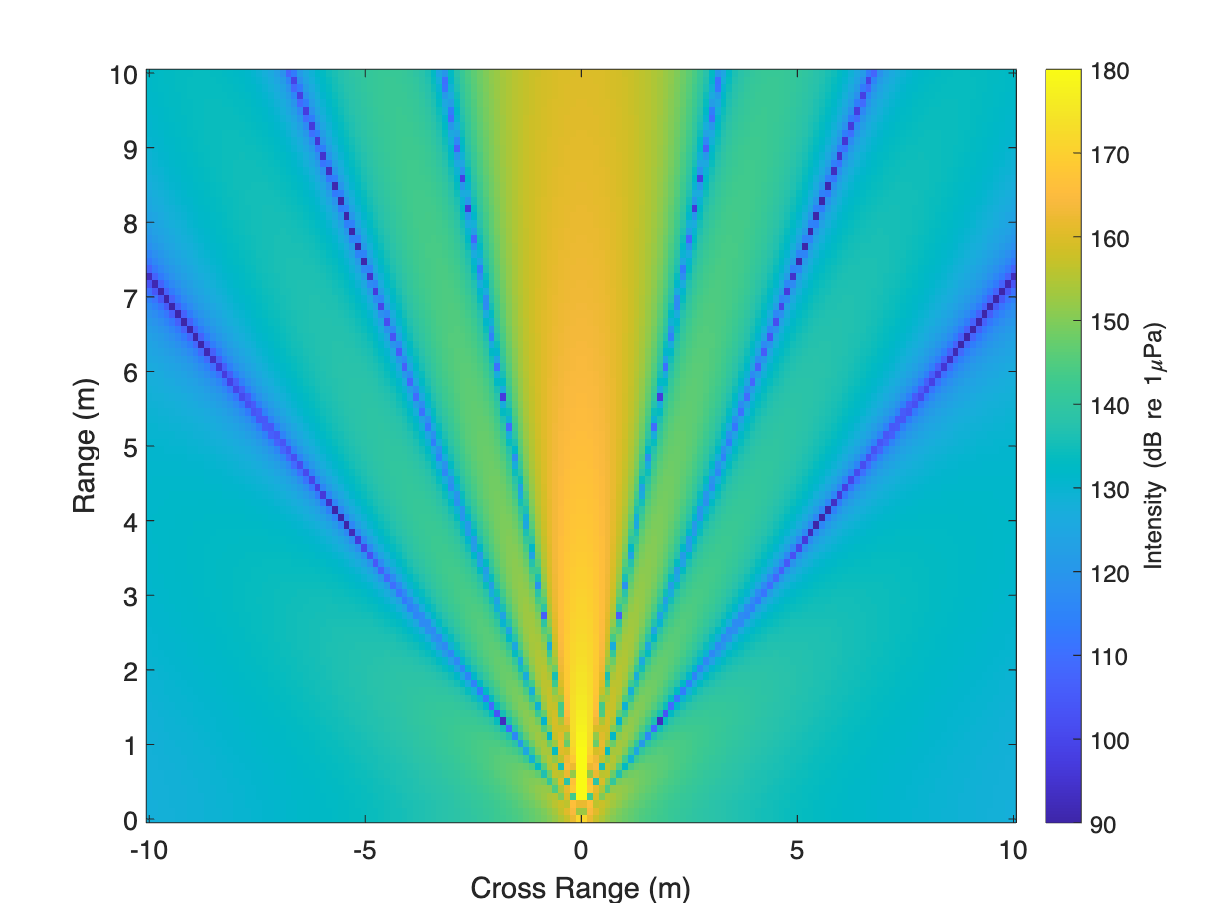

SL_dB = 180;
SL_lin = 10.^(SL_dB/20);
U0 = SL_lin/(rho0*c*k*a*a/2);

x = linspace(-r,r,150);
y = linspace(0,r,100);

[X,Y] = meshgrid(x,y);

thetaXY = atan2(X,Y);
rXY = sqrt(X.^2 + Y.^2);
u1 = k.*a.*sin(thetaXY);
projIntXY = abs((rho0*c*k*U0*a*a./(2*rXY)).*...
    (2*besselj(1,u1)./u1)).^2;

figure(2)
if plotScale == 'Decibels'
    imagesc(x,y,10*log10(projIntXY))
    a2 = gca;
    a2.YDir = 'normal';
    colorbar
    a2.FontSize = 12;
    a2.CLim = SL_dB - [90 0];
    a2.XLabel.String = 'Cross Range (m)';
    a2.YLabel.String = 'Range (m)';
    cb2 = colorbar;
    cb2.XLabel.String = 'Intensity (dB re 1\muPa)';
else
   imagesc(x,y,projIntXY/10^6)
    a2 = gca;
    a2.YDir = 'normal';
    cb2 = colorbar;
    cb2.XLabel.String = 'Intensity (\muPa^2)';
    a2.FontSize = 12;
    a2.CLim = 10.^((SL_dB - [90 0])/10); 
    a2.XLabel.String = 'Cross Range (m)';
    a2.YLabel.String = 'Range (m)';
end

### Far-field approximation compared to the full field

One important property of the far-field of a transducer is that the sound in this region all appears to coming from a single point on the transducer. This is what leads to the $1/r^2$ decrease in the intensity with range. Near the face of the transducer, this is no longer true and there is a region where the sound from one part of the transducer is interfering with sound from other parts of the transducer and there are no clear beams. This region is refered to as the **near-field** of the transducer. There is no simple mathematical expression for the sound field in this region, so in the widget below the sound field is calculated numerically to compare with the far-field solution. In the upper left plot is the far-field approximation of the sound field where regardless of how close you get to the transducer face, the field will always appear to come from a point at the center of the transducer. In the upper right plot, the true field of the transducer is numerically calculated. If the plotted range and cross-range is large, the two plots will look very similar. However if the range and cross-range start to get close to the radius of the transducer, the true field becomes very complicated.  The lower plot shows the field along the main axis of the transducer. Far from the face, the far-field and numerical calculation are very similar. Close to the transducer, the field begins to oscillate with strong nulls and peaks. There are a number of ways to estimate when this transition between near-field and far-field occurs. One useful estimate is that the range from the transducer needs to satisfy $r \gg 2a$ and $r \gg \pi a^2/\lambda$. In these calculations, the speed of sound is $c = 1500$ m/s and using this $c = f \lambda$, you can varify that this conditions hold as you change the frequency and radius of the transducer. 

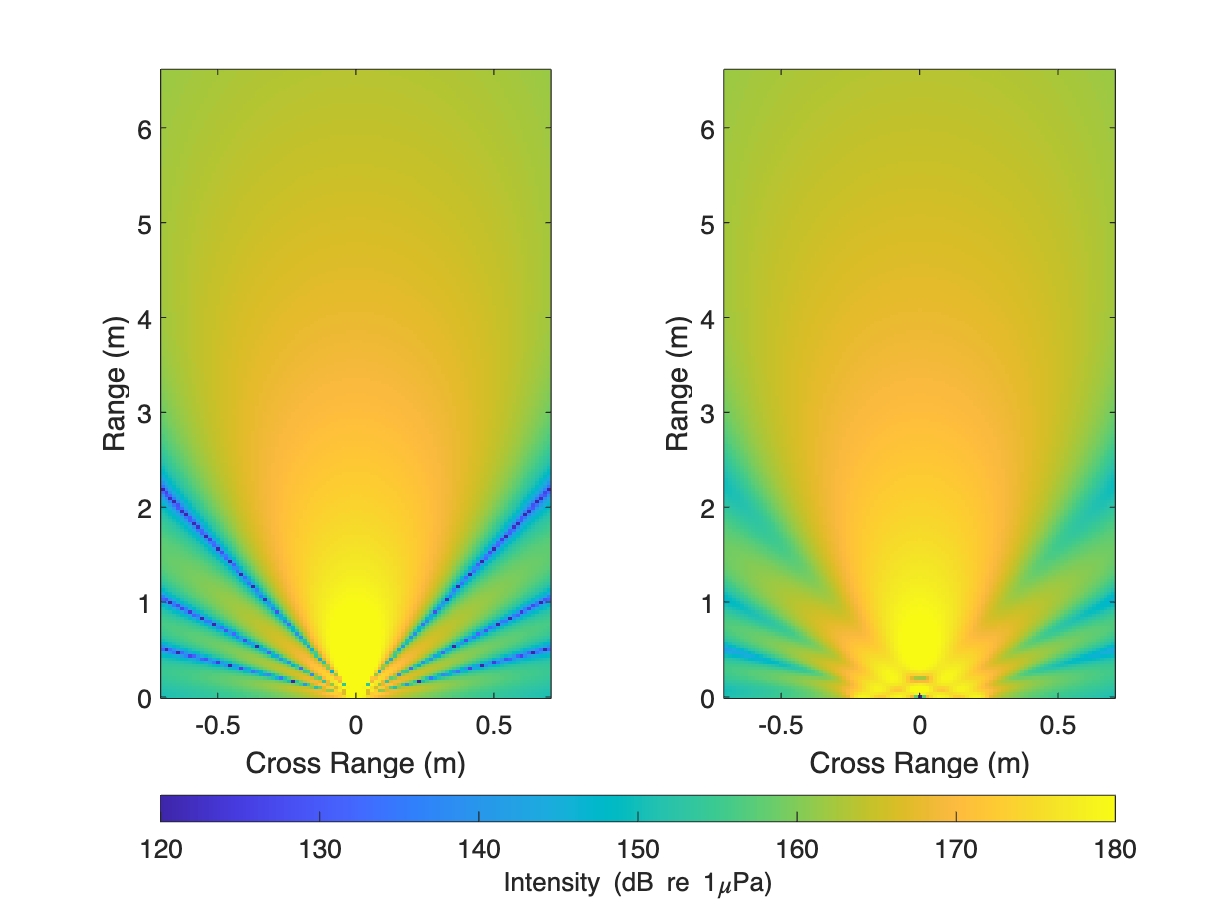

r1 = 6.6;
w1 = 0.7;
x1 = linspace(-w1,0,50);
x1 = [x1,-x1(end-1:-1:1)];
y1 = linspace(0,r1,200);

[X1,Y1] = meshgrid(x1,y1);

thetaXY1 = atan2(X1,Y1);
rXY1 = sqrt(X1.^2 + Y1.^2);
u11 = k.*a.*sin(thetaXY1);
projIntXY1 = abs((rho0*c*k*U0*a*a./(2*rXY1)).*...
    (2*besselj(1,u11)./u11)).^2;
[~,indX1] = min(abs(x1 - 0));
projIntXY1(:,indX1) = abs((rho0*c*U0*k*a*a./(2*rXY1(:,indX1))).*...
    (2*0.5)).^2;


sigmaP = linspace(0,a,200);
phiP = linspace(0,2*pi,200);
dsigmaP = diff(sigmaP(1:2));
dphiP = diff(phiP(1:2));
for jX = 1:length(x1)
    for jY = 1:length(y1)

        rPXY1 = sqrt(rXY1(jY,jX).^2 + sigmaP.^2 + 2*rXY1(jY,jX).*sigmaP.*...
            sin(thetaXY1(jY,jX)).*(cos(thetaXY1(jY,jX)).*cos(phiP.') + sin(thetaXY1(jY,jX)).*sin(phiP.')));
        intValXY1(jY,jX) = sum(sum(sigmaP.*dsigmaP.*dphiP.*exp(-1i*k*rPXY1)./rPXY1));

    end
end

nfprojIntXY = abs((1i*rho0*c*U0*k/(2*pi).*intValXY1).^2);

figure(3)
clf
% subplot(1,2,1)
tiledlayout(1,2)
nexttile
imagesc(x1,y1,10*log10(projIntXY1))
a2 = gca;
a2.YDir = 'normal';
% colorbar
a2.FontSize = 12;
a2.CLim = SL_dB - [60 0];
a2.XLabel.String = 'Cross Range (m)';
a2.YLabel.String = 'Range (m)';

% subplot(1,2,2)
nexttile
imagesc(x1,y1,10*log10(nfprojIntXY))
a2 = gca;
a2.YDir = 'normal';
% colorbar
a2.FontSize = 12;
a2.CLim = SL_dB - [60 0];
a2.XLabel.String = 'Cross Range (m)';
a2.YLabel.String = 'Range (m)';
cb2 = colorbar;
cb2.Layout.Tile = 'south';
cb2.Label.String = 'Intensity (dB re 1\muPa)';
cb2.FontSize = 12;

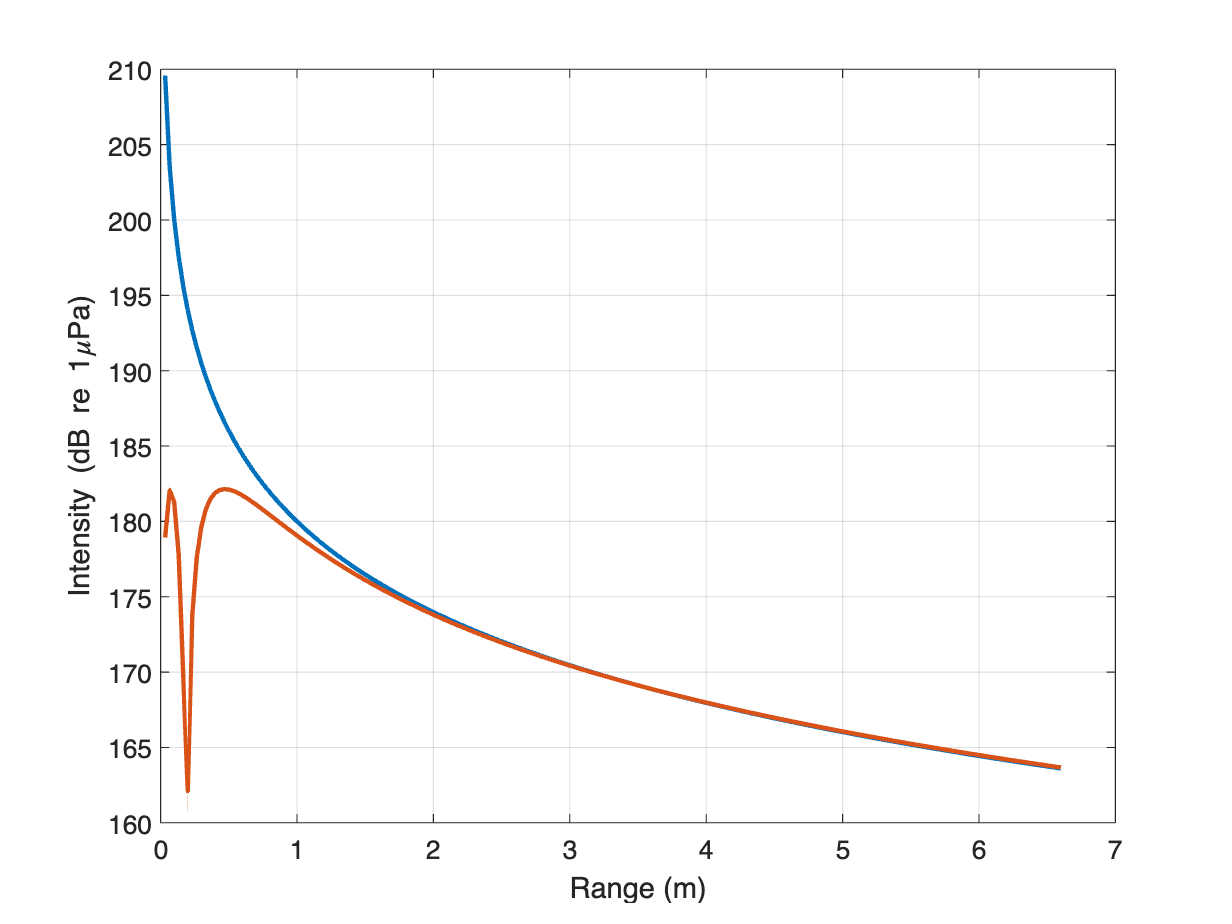



figure(4)
plot(y1,10*log10(projIntXY1(:,indX1)),...
    y1,10*log10(nfprojIntXY(:,indX1)),'linewidth',2)
a5 = gca;
a5.XLabel.String = 'Range (m)';
a5.YLabel.String = 'Intensity (dB re 1\muPa)';
a5.FontSize = 12;
grid on


waveLength = c/(f*1000);
r_est1 = (pi*a.^2)/waveLength;
r_est2 = 2*a;



### Rectangular transducer